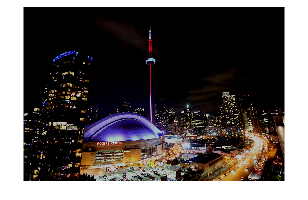

% Load the image
img = imread('toronto.jpg');

% Reduce the brightness
img = reduce_brightness(img, 50, 'subtract');

% Resize image 
% img = imresize(img, [360 480]); 

% Convert RGB to YCbCr
img_YCbCr = rgb2ycbcr(img);
Y = img_YCbCr(:,:,1);

% Display the image
imshow(img);


% Compute the average pixel intensity
avg_intensity_orig = mean2(Y);

% Display the average pixel intensity
disp(['Average pixel intensity: ' num2str(avg_intensity_orig)]);

Average pixel intensity: 40.1018


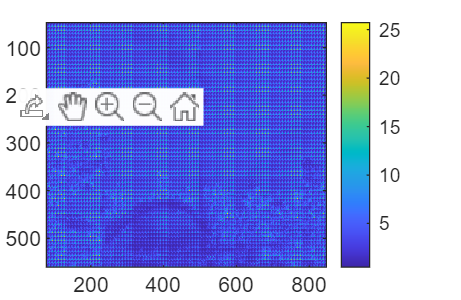

% For YCbCr images

% Compute the JND thresolds at a pixel level
jnd_Y = JND_dct(Y);

% Visualize the JND thresholds
imagesc(jnd_Y)
colorbar


% Compute the mean JND threshold
jnd_Y = 3.*jnd_Y;
jnd_mean = mean2(jnd_Y)

jnd_mean = 11.6690

jnd_mod = jnd_mean - jnd_Y;

% Update image based on the JND thresholds from the Y channel to generate a new image
jnd_img_Y = img_YCbCr;
jnd_img_Y(:,:,1) = uint8(double(Y) + round(jnd_mod));
new_img_jnd = ycbcr2rgb(jnd_img_Y); % convert back to RGB
new_img_jnd(new_img_jnd < 0) = 0;
new_img_jnd(new_img_jnd > 255) = 255;

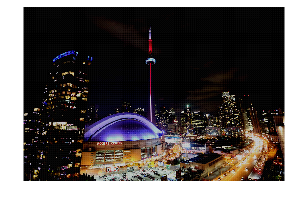

% Display the new image
imshow(new_img_jnd)


% Compute the average pixel intensity
new_img_YCbCr = rgb2ycbcr(new_img_jnd);
avg_intensity_jnd = mean2(new_img_YCbCr(:,:,1));
% intensity_dif = avg_intensity_orig - avg_intensity_jnd;

% Display the average pixel intensity
disp(['Average pixel intensity: ' num2str(avg_intensity_jnd)]);

Average pixel intensity: 42.7332


% Save the images to an output directory
imwrite(img, ['output_dct/input_image_' num2str(avg_intensity_orig) '.jpg'], 'jpg');
imwrite(new_img_jnd, ['output_dct/output_image_jnd_' num2str(avg_intensity_jnd) '.jpg'], 'jpg');
% imwrite(new_img_uniform, ['output/output_image_uniform_' num2str(avg_intensity_uniform) '.jpg'], 'jpg');